power = [50 75 100 125 150 175 200 225 250 275 300 325 350 375 400 425 450 475 485];
power = transpose(power);
power = power/1000;
size(power)

ans =     19     1



speed = [8414 11985 13823 15490 16851 18122 19334 20546 21868 23218 24568 25568 26403 27239 28264 29297 30294 31211 31578];
speed = transpose(speed);

size(speed)

ans =     19     1



f = fitlm(speed,power) % speed torque function

f = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)      -0.17453      0.015926    -10.959    3.9789e-09
    x1             2.0105e-05    6.8355e-07     29.413    5.0803e-16


Number of observations: 19, Error degrees of freedom: 17
Root Mean Squared Error: 0.0199
R-squared: 0.981,  Adjusted R-Squared: 0.98
F-statistic vs. constant model: 865, p-value = 5.08e-16

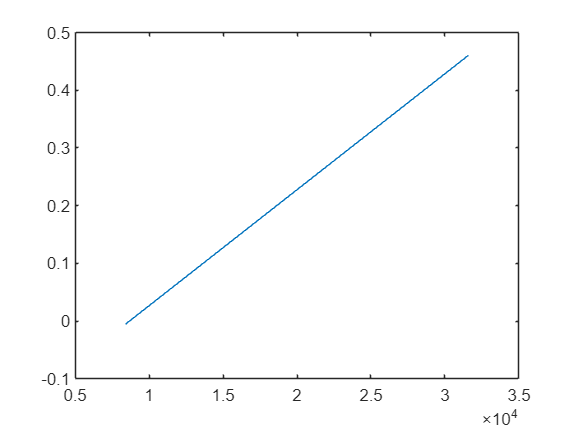


x = speed;
y = -0.17453 + 2.0105e-05*(x);


plot(x,y);


altitude = [1.0 1.25 1.5 1.75 2.0];
altitude = transpose(altitude);
y_scaling_values = [1.2 1.05 0.95 0.9 0.85];
y_scaling_values = transpose(y_scaling_values);
f = fitlm(altitude,y_scaling_values) % speed torque function

f = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)       1.5      0.077567     19.338    0.00030204
    x1              -0.34      0.050332    -6.7551     0.0066272


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 0.0398
R-squared: 0.938,  Adjusted R-Squared: 0.918
F-statistic vs. constant model: 45.6, p-value = 0.00663

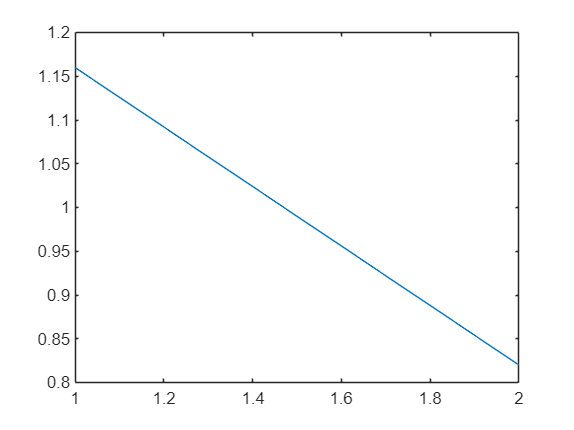


x = altitude;
y = 1.5 + -0.34*(x);

plot(x,y);